num_units = 0;
units_nwb_idx = [];
units_tbl_idx = [];
for ii = 1 : numel(nwb)

    units_per_nwb(ii) = sum(nwb{ii}.units.vectordata.get('quality').data(:)==1); 
    num_units = num_units + units_per_nwb(ii);
    units_nwb_idx = [units_nwb_idx repmat(ii, 1, units_per_nwb(ii))];
    units_tbl_idx = [units_tbl_idx find(strcmp(nwb{ii}.units.vectordata.get('quality').data(:),'good')).'];

end

Dot indexing is not supported for variables of this type.

lfp_nwb_idx = [];
lfp_tbl_idx = [];
for ii = 1 : numel(nwb)

    lfp_per_nwb(ii) = size(nwb{ii}.acquisition.get('probe_0_lfp').electricalseries.get('probe_0_lfp_data').data(:,:),1); 
    lfp_nwb_idx = [lfp_nwb_idx repmat(ii, 1, lfp_per_nwb(ii))];
    lfp_tbl_idx = [lfp_tbl_idx 1:lfp_per_nwb(ii)];

end

idx_units = 624;

figure;
num_channels = numel(nwb{units_nwb_idx(idx_units)}.general_extracellular_ephys_electrodes.vectordata.get('probe').data(:));
nwb_waves = reshape(nwb{units_nwb_idx(idx_units)}.units.waveform_mean.data(:,:), 82, num_channels, []);
peak_channel = nwb{units_nwb_idx(idx_units)}.units.vectordata.get('peak_channel_id').data(units_tbl_idx(idx_units))+1;
plot(nwb_waves(:,peak_channel,units_tbl_idx(idx_units)))

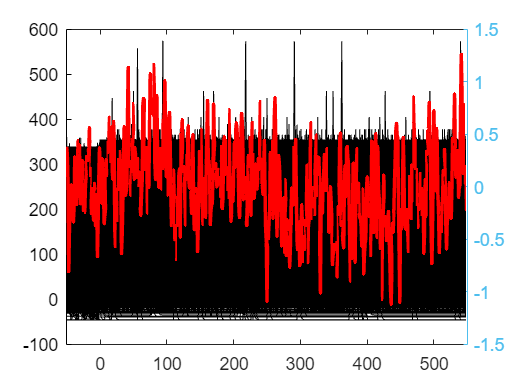


u_dat = nwb{units_nwb_idx(idx_units)}.processing.get('convolved_spike_train').nwbdatainterface.get('convolved_spike_train_data').data(units_tbl_idx(idx_units),:);
ts = nwb{units_nwb_idx(idx_units)}.processing.get('convolved_spike_train').nwbdatainterface.get('convolved_spike_train_data').timestamps(:);
evs = nwb{units_nwb_idx(idx_units)}.intervals.get('passive_glo').start_time.data(:);
p45s = nwb{units_nwb_idx(idx_units)}.intervals.get('passive_glo').vectordata.get('correct').data(:)==1 & ...
    (nwb{units_nwb_idx(idx_units)}.intervals.get('passive_glo').vectordata.get('orientation').data(:)==45 | ...
    nwb{units_nwb_idx(idx_units)}.intervals.get('passive_glo').vectordata.get('orientation').data(:)==135);
idxs = nearestIdx(ts, evs(p45s));
m_dat = pullVecs(u_dat, idxs, [50 550]); 
plot(-50:550, squeeze(baseline_correct(m_dat,1:50)), 'color', 'k') 
hold on;
yyaxis right
plot(-50:550, squeeze(mean(baseline_correct(m_dat,1:50),3)), 'color', 'r', 'linewidth', 2)
set(gca, 'xlim', [-50 550])

idx_session = 1;

u_dat = nwb{idx_session}.acquisition.get('EyeTracking').spatialseries.get('eye_tracking').data(:,:);

Error using indexing
The specified key is not present in this container.

Error in types.untyped.Set/get (line 165)
                o{i} = obj.map(name{i});

u_chan = size(u_dat,1);

idx_eye = 1;

figure;
ts = nwb{idx_session}.acquisition.get('EyeTracking').spatialseries.get('eye_tracking').timestamps(:);
evs = nwb{idx_session}.intervals.get('passive_glo').start_time.data(:);
p45s = nwb{idx_session}.intervals.get('passive_glo').vectordata.get('correct').data(:)==1 & ...
    (nwb{idx_session}.intervals.get('passive_glo').vectordata.get('orientation').data(:)==45 | ...
    nwb{idx_session}.intervals.get('passive_glo').vectordata.get('orientation').data(:)==135);
idxs = nearestIdx(ts, evs(p45s));
m_dat = pullVecs(u_dat(idx_eye,:), idxs, [50 550]); 
plot(-50:550, squeeze(baseline_correct(m_dat,1:50)), 'color', 'k') 
hold on;
yyaxis right
plot(-50:550, squeeze(mean(baseline_correct(m_dat,1:50),3)), 'color', 'r', 'linewidth', 2)
set(gca, 'xlim', [-50 550]) 

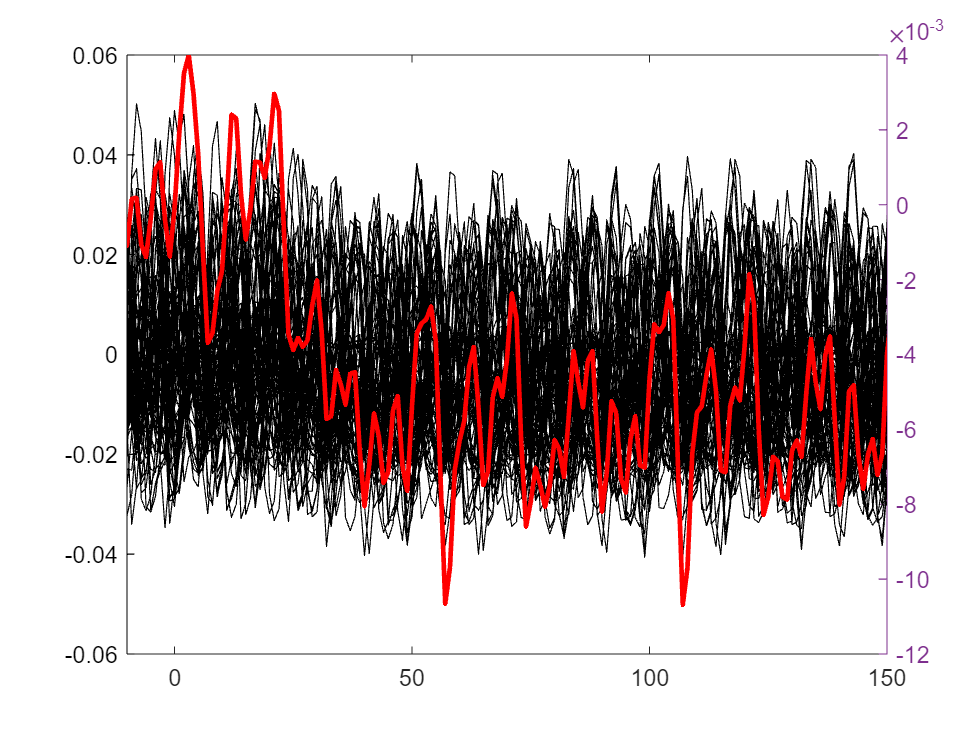

u_dat = nwb.acquisition.get('photodiode_1_tracking').timeseries.get('photodiode_1_tracking_data').data(:);
%[bwb, bwa] = butter(2, 250/500, 'low');
%u_dat = filtfilt(bwb, bwa, u_dat);

figure;
ts = nwb.acquisition.get('photodiode_1_tracking').timeseries.get('photodiode_1_tracking_data').timestamps(:);
evs = nwb.intervals.get('passive_glo').start_time.data(:);
p45s = nwb.intervals.get('passive_glo').vectordata.get('correct').data(:)==1 & ...
    (nwb.intervals.get('passive_glo').vectordata.get('orientation').data(:)==45 | ...
    nwb.intervals.get('passive_glo').vectordata.get('orientation').data(:)==135);
idxs = nearestIdx(ts, evs(p45s));
m_dat = pullVecs(u_dat', idxs, [50 550]); 
plot(-50:550, squeeze(baseline_correct(m_dat,1:50)), 'color', 'k') 
hold on;
yyaxis right
plot(-50:550, squeeze(mean(baseline_correct(m_dat,1:50),3)), 'color', 'r', 'linewidth', 2)
set(gca, 'xlim', [-10 150]) 

idx_session = 2;

u_dat = common_average_reference(nwb{idx_session}.acquisition.get('probe_0_lfp').electricalseries.get('probe_0_lfp_data').data(:,:));
%u_dat = common_average_reference(nwb{idx_session}.acquisition.get('probe_0_muae').electricalseries.get('ElectricalSeries').data(:,:));
u_chan = size(u_dat,1);

idx_lfp = 9;

figure;
ts = nwb{idx_session}.acquisition.get('probe_0_lfp').electricalseries.get('probe_0_lfp_data').timestamps(:);
evs = nwb{idx_session}.intervals.get('passive_glo').start_time.data(:);
 p45s = nwb{idx_session}.intervals.get('passive_glo').vectordata.get('correct').data(:)==1 & ...
     (nwb{idx_session}.intervals.get('passive_glo').vectordata.get('orientation').data(:)==45 | ...
     nwb{idx_session}.intervals.get('passive_glo').vectordata.get('orientation').data(:)==135);
%p45s = nwb{idx_session}.intervals.get('passive_glo').vectordata.get('codes').data(:)== 20;
idxs = nearestIdx(ts, evs(p45s));
m_dat = rmOutlier(baseline_correct(pullVecs(u_dat, idxs, [50 550]),1:50)); 
plot(-50:550, squeeze(m_dat(idx_lfp,:,:)), 'color', 'k') 
hold on;
yyaxis right
plot(-50:550, squeeze(nanmean(m_dat(idx_lfp,:,:),3)), 'color', 'r', 'linewidth', 2)
set(gca, 'xlim', [-50 550]) 

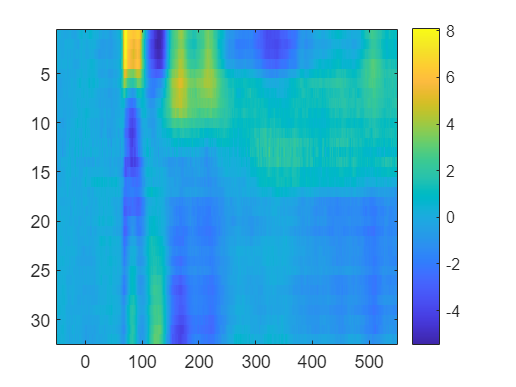

figure;
imagesc(-50:550, 1:u_chan, nanmean(m_dat,3))
set(gca, 'xlim', [-50 550]) 
colorbar